# APUNTES INICIALES

## Testing

Podemos cambiar el formato de salida de los numeros:

format short; pi

ans = 3.1416

format short e; pi

ans =    3.1416e+00


format long; pi

ans =    3.141592653589793


format long e; pi

ans =      3.141592653589793e+00


format % Para volver al estado original

Para hacer vectores:

v = [1:0.1:10]

v =     1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000    2.3000    2.4000    2.5000    2.6000    2.7000    2.8000    2.9000    3.0000    3.1000    3.2000    3.3000    3.4000    3.5000    3.6000    3.7000    3.8000    3.9000    4.0000    4.1000    4.2000    4.3000    4.4000    4.5000    4.6000    4.7000    4.8000    4.9000    5.0000    5.1000    5.2000    5.3000    5.4000    5.5000    5.6000    5.7000    5.8000    5.9000


M = [v;v;v;v;v]

M =     1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000    2.3000    2.4000    2.5000    2.6000    2.7000    2.8000    2.9000    3.0000    3.1000    3.2000    3.3000    3.4000    3.5000    3.6000    3.7000    3.8000    3.9000    4.0000    4.1000    4.2000    4.3000    4.4000    4.5000    4.6000    4.7000    4.8000    4.9000    5.0000    5.1000    5.2000    5.3000    5.4000    5.5000    5.6000    5.7000    5.8000    5.9000
    1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000    2.3000    2.4000    2.5000    2.6000    2.7000    2.8000    2.9000    3.0000    3.1000    3.2000    3.3000    3.4000    3.5000    3.6000    3.7000    3.8000    3.9000    4.0000    4.1000    4.2000    4.3000    4.4000    4.5000    4.6000    4.7000    4.8000    4.9000    5.0000    5.1000    5.2000    5.3000    5.4000    5.5000    5.6000    5.7000    5.8000    5

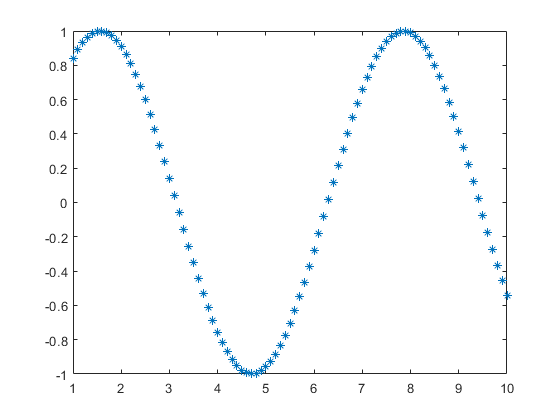

legend1 = legend(axes,'show');
set(legend1,...
    'Position',[0.72559523974501 0.148412699548025 0.1464285697788 0.047619046483721]);
plot(v,sin(v), '*')

## Aritmetica de Matlab

a = 4/3

a = 1.3333

b = a-1

b = 0.3333

c = b + b + b

c = 1.0000

e = 1 - c

e = 2.2204e-16

## Grafica

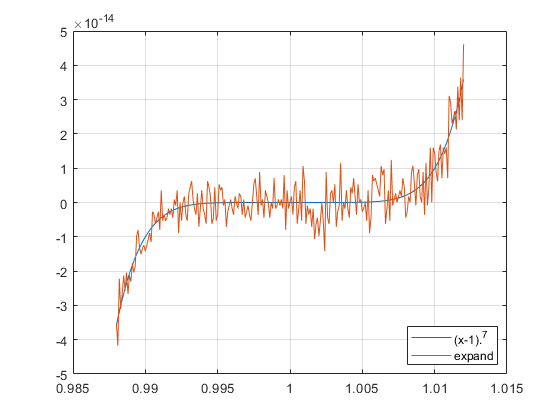

x = 0.988:0.0001:1.012;
y1 = (x-1).^7;  % Polinomio
y2 = x.^7 - 7*x.^6 + 21*x.^5 - 35*x.^4 + 35*x.^3 - 21*x.^2 + 7*x - 1; % Polinomio descompuesto


grid;
legend('(x-1).^7', 'expand', 'location', 'best')

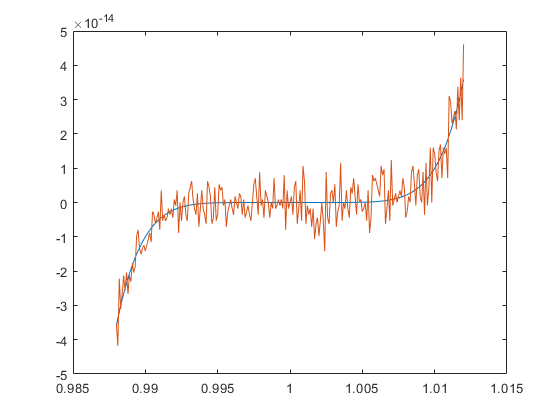


plot(x,y1, x,y2);

## Symbolic Math

syms t f(t)
f(t) = t^2 + 2*atan(pi*t)

$$f(t) = 2\,\mathrm{atan}\left(\pi \,t\right)+t^{2}$$

f(3)

$$ans = 2\,\mathrm{atan}\left(3\,\pi \right)+9$$

vpa(f(3), 50000)

Error using digits (line 42)
Expecting integer between 2 and 2^29.

Error in sym/vpa (line 30)
        digits(d);

diff(f(t), t)
fplot(f)
tayor(f(t), t,0,8)